# **Implementación EC en matlab de modulación digital y analógica**

Andrés Fernando Jerez Medina - 2190416

Jorge Eduardo Angarita Perez - 2190427

Sergio Sebastián Oliveros Sepulveda - 2190396 

## **Punto 2:**

Al igual que en ejercicio anterior, fue necesario iniciar introduciendo los parámetros requeridos. Siendo el primero de estos la frecuencia del mensaje, la cual ya es fija y vale 100 Hz. Después, se tomaron las frecuencias de portadora y muestreo, siendo estas 10 y 100 veces la frecuencia del mensaje respectivamente. Se usó el parámetro *nper* para que el tiempo de observación fueran exactamente 2 periodos de la señal mensaje.

fm = 100;                    %Frecuencia del mensaje

Ac = 1;                      %Amplitud de la portadora
fc = fm*10;                  %Frecuencia de la portadora
fs = fc*10;                  %Frecuencia de muestreo
Ts = 1/fs;                   %Periodo de muestreo

nper = 2;                    %Periodos de la señal
Tend = 1/fm*nper;            %Tiempo de simulación

Finalmente, se escogió el valor de $D_f$ teniendo en cuenta la siguiente fórmula encontrada en el libro de comunicaciones analógicas y digitales de León Couch, la cual relaciona la máxima desviación de frecuencia en una modulación FM con el anterior parámetro:


$$\Delta \;f_{\textrm{máx}} =D_f \frac{V_p }{2\pi \;}$$


Donde $V_p$ es el máximo de la señal $m\left(t\right)$, por lo que despejando, se tiene $D_f$ dada una desviación máxima deseada, la cual en este caso fue de 300 para poder detallar mejor los cambios de frecuencia:

dfMax = 400;                 %Desviación máxima
Df = 2*pi/10*dfMax;          %Constante de desviación de frecuencia en modulador

Con esto se pudo definir la función mensaje:

t = 0:Ts:(Tend-Ts);          %Tiempo
n = length(t);               %Número de muestras
m_t = 10*sin(2*pi*fm*t);     %Construcción de la señal mensaje 

Ahora, a partir de esto último construimos las funciones $x\left(t\right)$ y$y\left(t\right)$  de la siguiente manera:


$$x\left(t\right)=A_c \cos \left(D_f \int_{-\infty }^t m\left(\alpha \;\right)d\alpha \;\right)$$



$$y\left(t\right)=A_c \sin \left(D_f \int_{-\infty }^t m\left(\alpha \;\right)d\alpha \;\right)$$


Se puede observar, que ambos componentes dependen de un valor correspondiente a la multipicación de $D_f$ con la integral del mensaje, al estar en el dominio discreto esta integral fue definida como una sumatoria de cada uno de valores (usando *cumsum*) multiplicado por el tiempo de muestreo, realizando así una aproximación de esta operación:   

x_t = Ac*cos(Df*cumsum(m_t)*Ts);                %Componente en fase
y_t = Ac*sin(Df*cumsum(m_t)*Ts);                %Componente en cuadratura
g_t = x_t + 1j*y_t;                             %Envolvente compleja

s_t = x_t.*cos(2*pi*fc*t)-y_t.*sin(2*pi*fc*t);  %Señal modulada

Las señales obtenidas fueron graficadas en el tiempo usando el vector *t *antes definido. A continuación, pueden observarse las 4 gráficas, del mensaje, las partes real e imaginaria de la envolvente compleja y la modulación $s\left(t\right)$.

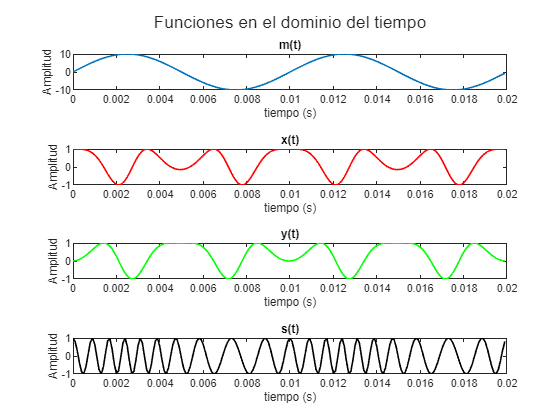

p = tiledlayout(4,1);
title(p,"Funciones en el dominio del tiempo")

nexttile; plot(t,m_t,'LineWidth',1.2); title("m(t)"); 
ylabel("Amplitud"); xlabel("tiempo (s)");

nexttile; plot(t,x_t,'red','LineWidth',1.2); title("x(t)"); 
ylabel("Amplitud"); xlabel("tiempo (s)");

nexttile; plot(t,y_t,'green','LineWidth',1.2); title("y(t)"); 
ylabel("Amplitud"); xlabel("tiempo (s)");

nexttile; plot(t,s_t,'black','LineWidth',1.2); title("s(t)"); 
ylabel("Amplitud"); xlabel("tiempo (s)");

Al revisar los 2 componentes de la envolvente compleja, se tienen dos funciones periódicas pero que ya no poseen la forma típica de una sinusoide. Se tiene además un desfase entre $x\left(t\right)$ y $y\left(t\right)$ pues en la primera se aplica una función *coseno *mientras que en la segunda un *seno*. En ambos casos se tiene la amplitud configurada antes.

En el caso de $s\left(t\right)$, se tiene una sinusoide con frecuencia variable, identificando cómo la señal cambia más rápido cuando la amplitud es mayor, mientras que su periodo aumenta cuando esta tiene una polaridad negativa. 

Para observar el espectro de las señales en el dominio de la frecuencia se realizó la tranformada de Fourier de cada función:

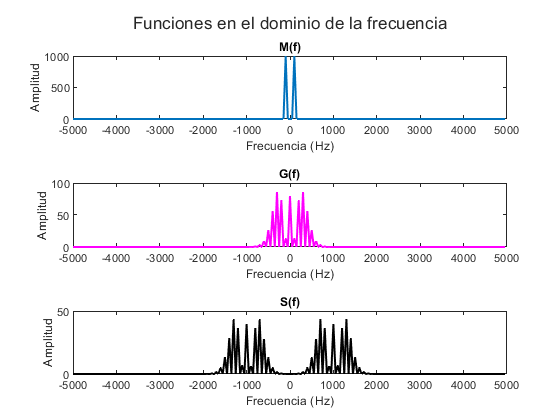

m_f = fftshift(fft(m_t));
g_f = fftshift(fft(g_t));
s_f = fftshift(fft(s_t));

f = (-n/2:n/2 - 1)*(fs/n);
figure
t = tiledlayout(3,1);
title(t,"Funciones en el dominio de la frecuencia")

nexttile; plot(f,abs(m_f),'LineWidth',1.2); title("M(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,abs(g_f),'magenta','LineWidth',1.2); title("G(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,abs(s_f),'black','LineWidth',1.2); title("S(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")

La primera gráfica, al representar una señal sinusoidal, consiste únicamente de 2 picos centrados en las frecuencias de esta función, mientras que la envolvente compleja posee un espectro con muchos más componentes, que indicarían los armónicos necesarios para recrear las funciones correspondientes a los componentes en fase y cuadratura. Finalmente, al igual que en punto anterior, se tienen dos copias de $G\left(f\right)$ centradas en ${\pm f}_c$, haciendo también que la amplitud tenga sea la mitad.

Y por último, se muestra la densidad espectral de potencia (PSD) de cada una de las señales vistas anteriormente:

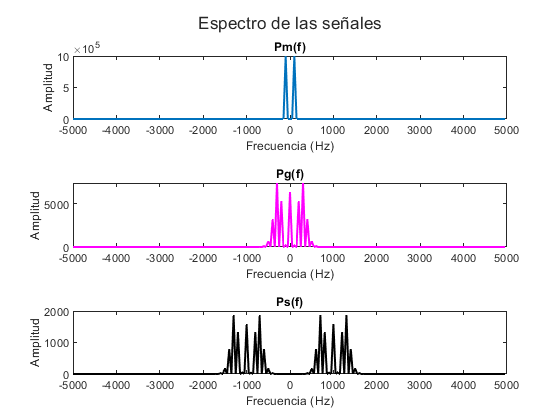

figure
t = tiledlayout(3,1);
title(t,"Espectro de las señales")
nexttile; plot(f,(abs(m_f).^2),'LineWidth',1.2); title("Pm(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,(abs(g_f).^2),'magenta','LineWidth',1.2); title("Pg(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,(abs(s_f).^2),'black','LineWidth',1.2); title("Ps(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")

Comparando los resultados con la gráfica de la representación en frecuencia anterior, se ve que ambas pares de curvas tienen la misma forma, variando únicamente su forma. 